# Eksamen F2022

Mathias Bruun Houmøller  -  202006837

format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

## Opgave 1

**a)**

clear

syms t
g = -9.81; % m/s^2
a_0 = g; % der omnavngives
v_0 = 180; % m/s

theta = 60; % grader
alpha = 20; % grader

disp("For y komposanten har vi strækningen for max højden")

For y komposanten har vi strækningen for max højden


disp("når hastigheden v er 0.")

når hastigheden v er 0.


disp("Vi finder tiden t til denne position")

Vi finder tiden t til denne position



v_y0 = sind(theta) * v_0 % y komposanten af hastigheden

v_y0 =        155.88



v_y_eq = v_y0 + a_0 * t % hastighedsligningen opstilles

$$v\_y\_eq = 90\,\sqrt{3}-\frac{981\,t}{100}$$


t_cal = solve(0 == v_y_eq, t); %tiden findes.
t_ = vpa(t_cal, 4) 

$$t\_ = 15.89$$


disp("Vi indsætter nu tiden i sted funktionen")

Vi indsætter nu tiden i sted funktionen


disp("ved at integrere hastighedsfunktionen")

ved at integrere hastighedsfunktionen



y(t) = int(v_y_eq, t) % integrere hastihedsfunktione

$$y(t) = -\frac{9\,t\,\left(109\,t-2000\,\sqrt{3}\right)}{200}$$


fprintf("Max højden vi når er %f m", vpa(y(t_cal),4))

Max højden vi når er 1238.532110 m

**1,24 km er således den maximale højde vi kommer op på.**

**b)**

syms x

v_x0 = cosd(theta) * v_0 % y komposanten af hastigheden

v_x0 =     90




disp("Sted funktionen afhænger her kun af start hastigheden")

Sted funktionen afhænger her kun af start hastigheden


% displayFormula("x = v_x0 * t")
x_fun(t) = v_x0 * t

$$x\_fun(t) = 90\,t$$


x_fun_rampe(t) = v_x0 * t - v_x0 * t * cosd(alpha);

disp("Her kan t isolere og erstatte det i y-funktionen med x/v_x0")

Her kan t isolere og erstatte det i y-funktionen med x/v_x0


disp("Vi får ligningen")

Vi får ligningen



y(x) = v_y0 * x/v_x0 + a_0 * (x/v_x0)^2 / 2

$$y(x) = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$

**Vi har nu forskriften y(x) for projektilets banekurve som**


$$y\left(x\right)=\frac{v_{\mathrm{y0}}\,x}{v_{\mathrm{x0}}}+\frac{a_{0}\,x^2}{2\,{v_{\mathrm{x0}}}^2}'$$


Vi plotter nu rampen sammen med bane kurven


y_rampe(x) = sind(alpha) * x; % ligning for rampen
X_lin = linspace(0,2870,100); %linspace til plot

%plot af bane kurven
plot(X_lin, y(X_lin), "displayName", "Bane kurve")
hold on

plot(X_lin, y_rampe(X_lin), "displayName", "Rampe")

%formalia
% yline(double(y(t_cal)), 'g--', "displayName", "y-max")
yline(0, '--', "displayName", "0-linje")
grid()
legend('Location','NorthOutside')
ylabel('y-position(m)'), xlabel('x-position(m)')
hold off


**c)**



disp("afstanden R findes nu i skæringspunktet imellem rampen og banekurven")

afstanden R findes nu i skæringspunktet imellem rampen og banekurven


disp("Først findes x-afstanden")

Først findes x-afstanden


x_slut_eq = y(x) - y_rampe(x);

x_slut = solve(x_slut_eq == 0, x);

x_slut_ = vpa(x_slut(2), 5)

$$x\_slut\_ = 2295.5$$

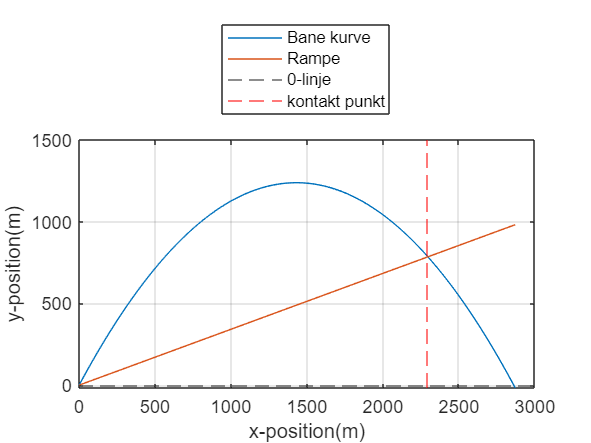


xline(double(x_slut_), 'r--', "displayName", "kontakt punkt")

disp("Vi kan nu finde rampens længde med x som")

Vi kan nu finde rampens længde med x som


R = vpa(x_slut(2) / cosd(alpha), 5)

$$R = 2442.8$$

**Rampen R er således  2,44 km**